# Fumbol

**Yaiza Cano, Narcís Terrado**

## 1. Escollir imatge i patró.

Primerament escollirem la imatge que voldrem utilitzar com a model i escollirem un tros d'imatge que serà el nostre patró.

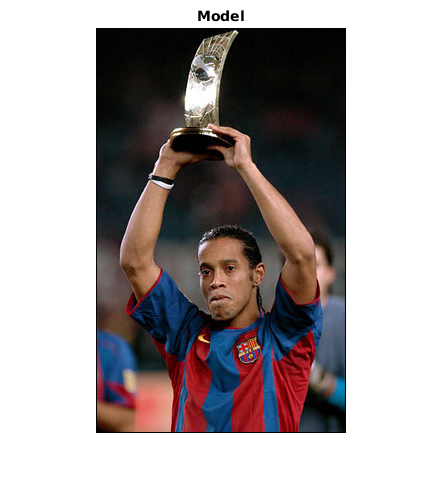

model = imread('model.jpg');
figure, imshow(model); title('Model');

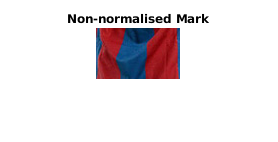


pattern = model(350:400,87:170,:);
figure, imshow(pattern); title('Non-normalised Mark');

## 2. Normalitzar colors i extreure'n l'histograma

Un cop escollit el patró, hem d'extreure els colors per fer l'histograma però, abans d'això, hem de normalitzar els colors per tal que la il·luminació de la imatge no afecti a les dades que volem extreure.

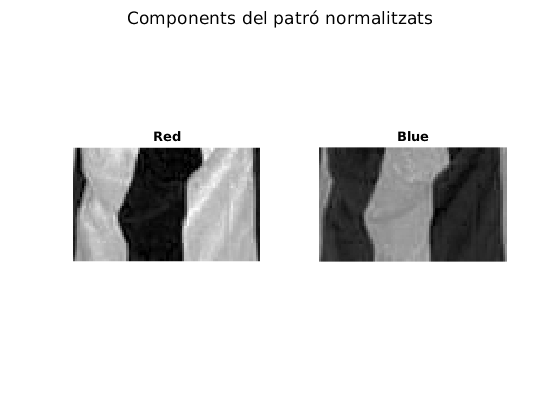

np = NormalizeRB(model); % Normalitzem tota la imatge
np = np(350:400,87:170,:); % Agafem el patró ara normalitzat

figure, sgtitle('Components del patró normalitzats')
subplot(1,2,1);imshow(np(:,:,1)); title('Red')
subplot(1,2,2);imshow(np(:,:,2)); title('Blue')

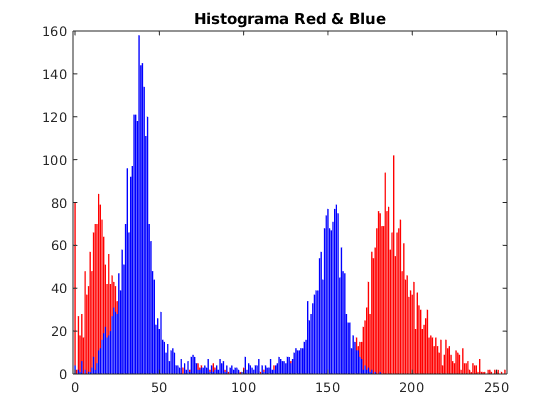


figure, [red, blue] = histRB(np); title('Histograma Red & Blue');

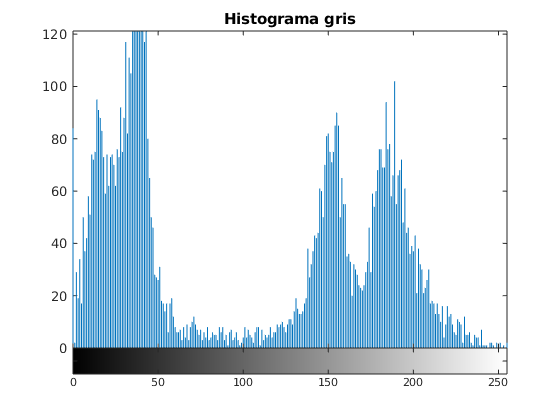

figure, imhist(np), title('Histograma gris');

## Functions

type NormalizeRB.m;


% Creem una  funci� per normalitzar els colors red i blue d'una imatge i, 
% per tant, els colors no es vegin afectats per la il�luminaci� d'aquesta. 
% El que obtindrem ser� una matriu de 3 dimesions rb amb dos plans on al 
% primer hi trobem el color red i al segon el blue, ambd�s normalitzats.

function [rb] = NormalizeRB(im)
    [rows, cols, ~] = size(im);
    im = double(im);
    rgb = im(:,:,1) + im(:,:,2) + im(:,:,3);
    rb = uint8(zeros(rows,cols,2));
    rb(:,:,1) = uint8(255*im(:,:,1)./rgb); 
    rb(:,:,2) = uint8(255*im(:,:,3)./rgb); 
end
